# Demo of AJIVE Random Direction Bound Analysis

## Load data

clc
clear
load data/ToyData.mat

## ***Set up***

nsim = 100;
vecr = [2, 3];
threp = 95;
iplot = 1; % make figure
iprint = 1; % save plot
figdir = 'figures/';

## Calculate Random Direction Bound

Input rank for X is 2
Input rank for Y is 3
The singular value of stacked row spaces among original datablocks are: 
1.41 	1.30 	
The 95% percentile bound of singular value for joint space is 1.36 
The principal angles between X and Y: 	10.99 	47.11 	
The 95% percentile bound of principal angle for joint space is 31.08
The 95% percentile of the largest singular value of stacked row space bases
under the null distribution is 1.16
The 5% percentile of the smallest principal angle between X and Y
under the null distribution is 70.25
p-value of the test is 0


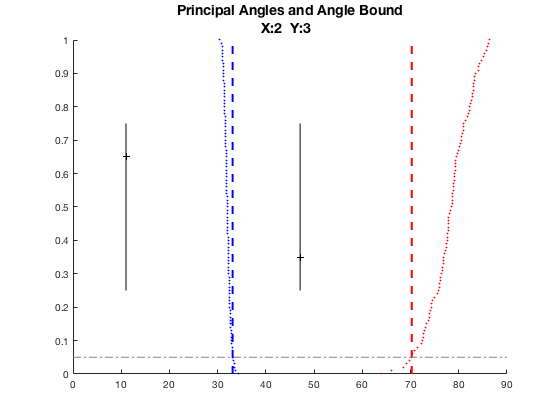

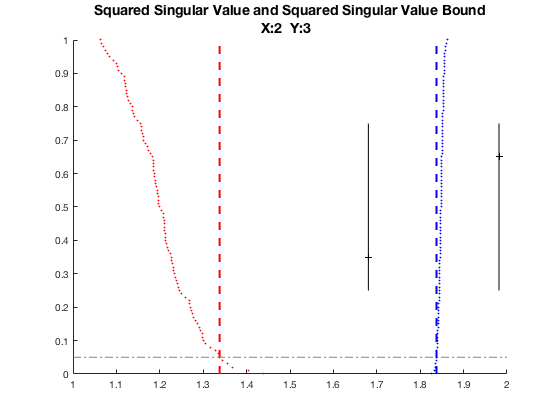

[pval, nullsv, svbound, ps_union, s_unions] = AJIVE_Rand_Dir_Bound( datablock, vecr, nsim, ...
                                                dataname, threp, iplot, iprint, figdir );